%clear();

%{
load("test_signal\sin1d0.mat");
Inp_sine = data{1}.Values.Data
Measure_sine = data{2}.Values.Data

TimeArr = data{1}.Values.Time

load("test_signal\ramp2d4.mat");
Inp_ramp = data{1}.Values.Data
Measure_ramp = data{2}.Values.Data

load("test_signal\pulse1d0.mat");
Inp_step = data{1}.Values.Data
Measure_step = data{2}.Values.Data

load("test_signal\stair1.mat");
Inp_stair = data{1}.Values.Data
Measure_stair = data{2}.Values.Data

load("test_signal\chirp1.mat");
Inp_chirp = data{1}.Values.Data
Measure_chirp = data{2}.Values.Data

Measure_test_signals = [
    Measure_sine;
    Measure_ramp;
    Measure_step;
    Measure_stair;
    Measure_chirp
];

save("test_signal\Test_Dataframe.mat")
%}
load("test_signal\Test_Dataframe.mat");

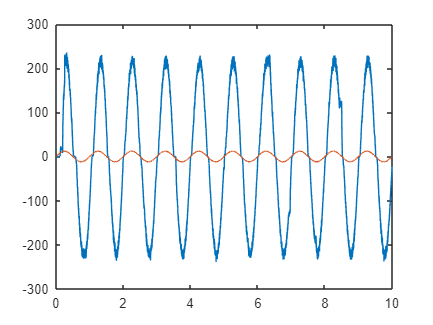

% Plot
figure(Name='Validation Testing Signal')
plot(TimeArr,Measure_sine,TimeArr,Inp_sine)

Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Store signals in arrays for easy iteration
Inp_test_signals = {Inp_sine, Inp_ramp, Inp_step, Inp_stair, Inp_chirp};
Measure_test_signals = {Measure_sine, Measure_ramp, Measure_step, Measure_stair, Measure_chirp};



% Loop through each test signal and plot in a separate figure
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Signal']);
    plot(TimeArr, Measure_test_signals{i}, TimeArr, Inp_test_signals{i});
    title([Test_signal_names{i}, ' Signal']);
    legend('Measured', 'Input');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Measured Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Measure_test_signals{i});
end
hold off;
title('Conclusion: Overlay of All Measured Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time');
ylabel('Amplitude');
grid on;